# AuE-6600 | Dynamic Performance of Vehicles

## Final Exam

### Problem 1: Stability Derivatives

Consider a bicycle model vehicle with the following parameters (SAE):

- 40% front weight

- 10 ft wheelbase

- The vehicle is known to be neutral steer.

The vehicle is driven in a steady-state fashion with the following conditions:

- Velocity = 66 ft/s

- Steer angle = - 40 deg at the steering wheel

- Steering ratio = 16

- Stabilizing yaw moment (including static and dynamic contributions) = 3200 lb.-ft

- Yaw rate = -12 deg/sec

Determine the following

- Static stability derivative

- Control moment derivative

- Yaw damping derivative

- Front and rear cornering stiffnesses

- Path radius

### Solution 1

% Given data
l = 10; % ft
l = l/3.281; % m
m_a = 0.6*l; % m
m_b = l-m_a; % m
v = 66; % ft/s
v = v/3.281; % m/s
delta = -40; % deg
delta = deg2rad(delta); % rad
SR = 16;
Mz_stab = 3200; % lb-ft
Mz_stab = Mz_stab*1.356; % kg-m
psi_dot = -12; % deg/s
psi_dot = deg2rad(psi_dot); % rad/s

Path radius

R = l/tan(abs(delta/SR));
fprintf("Path radius is %.4f m", R)

Path radius is 69.8073 m

Yaw damping derivative

Nr = Mz_stab/psi_dot; % since N_beta = 0 for neutral-steer
fprintf("Yaw damping derivative is %.4f N-m-s/rad", Nr)

Yaw damping derivative is -20718.1539 N-m-s/rad

Front and rear cornering stiffnesses

A = [m_a^2/v m_b^2/v; m_a -m_b];
B = [Nr; 0];
C_alpha = linsolve(A,B);
C_alpha_f = C_alpha(1);
C_alpha_r = C_alpha(2);
fprintf("Front cornering stiffness is %.4f N/rad and rear cornering stiffness is %.4f N/rad", ...
        C_alpha_f, C_alpha_r)

Front cornering stiffness is -74773.8891 N/rad and rear cornering stiffness is -112160.8337 N/rad

Static stability derivative

NB = m_b*C_alpha_r - m_a*C_alpha_f;
fprintf("Static stability derivative is %.4f N-m/rad", NB)

Static stability derivative is 0.0000 N-m/rad

Control moment derivative

Nd = -m_a*C_alpha_f;
fprintf("Control moment derivative is %.4f N-m/rad", Nd)

Control moment derivative is 136739.8156 N-m/rad

### Problem 2: Transport Theorem

A fire truck is moving forward at a speed of 35 miles/hour and is decelerating at the rate of 10 $\textrm{ft}/s^2$. Simultaneously, the ladder is being raised and extended. At the instant considered below, the angle of the ladder is 30⁰ and is increasing at the constant rate of 10 deg/sec. Furthermore, at this instant shown, the ladder extension b is 5 ft, with $\dot{b}$ = 2 ft/s and $\ddot{b}$ = −1 $\textrm{ft}/s^2$.

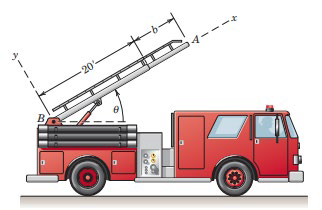

For this instant, determine the acceleration of the end A of the ladder

a. With respect to the truck and

b. With respect to the ground.

### Solution 2

Acceleration of the end A of the ladder with respect to the ground

% Given data
v_x = 35; % mph
v_x = v_x/3.281; % m/s
a_x = -10; % ft/s^2
a_x = a_x/3.281; % m/s^s
theta = deg2rad(30); % rad
theta_dot = deg2rad(10); % rad/s
b = 5; %ft
b = b/3.281; % m
b_dot = 2; % ft/s
b_dot = b_dot/3.281; % m/s
b_ddot = -1; % ft/s^2
b_ddot = b_ddot/3.281; % m/s^2

% Compute intermediate variables
a_Odash_A = a_x.*[cos(theta); -sin(theta); 0]; % linear acc. of ladder origin w.r.t. ground
a_p_B = [b_ddot; 0; 0]; % linear acc. of ladder end point w.r.t. ladder frame
alpha_B_A = [0; 0; 0]; % angular acc. of ladder frame w.r.t. ground
rho = [(20/3.281)+b; 0; 0]; % location of ladder end point w.r.t. ladder frame
W_B_A = [0; 0; theta_dot]; % angular vel. of ladder frame w.r.t. ground
v_p_B = [b_dot; 0; 0]; % linear vel. of ladder end point w.r.t. ladder frame

% Compute acceleration of ladder end w.r.t. ground
a_p_A = a_Odash_A + a_p_B + cross(alpha_B_A,rho) + 2*cross(W_B_A,v_p_B) + ...
        cross(W_B_A,cross(W_B_A,rho));

% Compute acceleration of ladder end w.r.t. truck
a_p_C = a_p_A - a_Odash_A;

fprintf("Acceleration (m/s^2) of ladder end A w.r.t. truck is:\n%.4f\ti\n%.4f\tj\n%.4f\tk", ...
        a_p_C(1),a_p_C(2),a_p_C(3));

Acceleration (m/s^2) of ladder end A w.r.t. truck is:
-0.5369	i
0.2128	j
0.0000	k

fprintf("Acceleration (m/s^2) of ladder end A w.r.t. ground is:\n%.4f\ti\n%.4f\tj\n%.4f\tk", ...
        a_p_A(1),a_p_A(2),a_p_A(3));

Acceleration (m/s^2) of ladder end A w.r.t. ground is:
-3.1764	i
1.7367	j
0.0000	k

### Problem 3: 2-DoF Bicycle Model with Load Transfer

A (linear) Bicycle Model of a snowplow is shown below, with a sketch of the real vehicle at the right. The snow is applying a constant lateral force Fs to the vehicle.

Here are the vehicle parameters:

- Weight = 40,000 lbs.

- Weight distribution: 40% front

- Roll distribution: 45% front

- Wheelbase: 15 fts

- Speed: 50 mph

- Distance d: 4 fts

- Snow Force, Fs: 1000 lbs.

- Height of CG: 4.7 ft.

- Trackwidth: 9 ft.

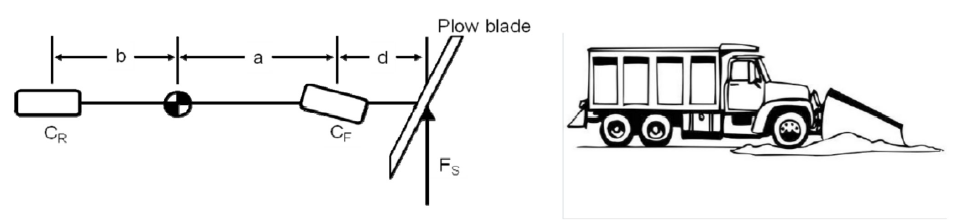

This vehicle is traveling at steady state in a circular motion with a radius of 500 ft. Determine the equations of motion for this system.

#### Part A:

For this part, ignore the lateral load transfer completely and determine:

A. Ackermann Steer Angle          F. Front Slip Angle

B. Lateral Acceleration                G. Rear Slip Angle

C. Yaw Rate                                H. Total Yaw Moment

D. Front Lateral Force                 I. Vehicle Sideslip Angle

E. Rear Lateral Force                  J. Steer Angle

The relationship between cornering stiffness and normal load of the tires is given as follows:


$$C_{\alpha } =a*F_{z\;} -b*F_z^2$$


a = 0.2196; b = 7.35 × 10−6

Fz in lb and C in lb/deg

#### Part B:

Consider the effects of lateral load transfer on normal load of tire with given roll distribution. Repeat Part A. Compare the results of Part A and Part B and comment on it.

### Solution 3

% Given data
wt = 40000; % lbs
wt = wt*4.4482189159; % N
m = wt/9.81; % kg
l = 15; % ft
l = l/3.281; % m
t = 9; % ft
t = t/3.281; % m
d = 4; % ft
d = d/3.281; % m
h_cr = 4.7; % ft
h_cr = h_cr/3.281; % m
m_a = 0.6*l; % m
m_b = l-m_a; % m
r_a = 0.45;
r_b = 1-r_a;
v = 50; % mph
v = v/2.237; % m/s
Fs = 1000; % lbs
Fs = Fs*4.4482189159; % N
R = 500; % ft
R = R/3.281; % m

#### Part A:

Ackermann Steer Angle

deltaA = atan2(l,R);
fprintf('The Ackermann steer angle is %.4f rad', deltaA);

The Ackermann steer angle is 0.0300 rad

Lateral Acceleration

a_y = v^2/R;
fprintf('The lateral acceleration is %.4f m/s^2', a_y);

The lateral acceleration is 3.2783 m/s^2

Yaw Rate

psi_dot = v/R;
fprintf('The yaw rate is %.4f rad/s', psi_dot);

The yaw rate is 0.1467 rad/s

Front and Rear Lateral Force

% Sum of forces: Fy_f + Fy_r = Fy + Fs
% Sum of moments: Fy_f*a -fy_r*b = Fs*(d+a)
A = [1 1; m_a -m_b];
B = [m*a_y+Fs; Fs*(d+m_a)];
Fy = linsolve(A,B);
Fy_f = Fy(1);
Fy_r = Fy(2);
fprintf('The front lateral force is %.4f N and rear lateral force is %.4f N',Fy_f,Fy_r);

The front lateral force is 29418.2189 N and rear lateral force is 34489.5206 N

 Front and Rear Slip Angle

% Calculate cornering stiffness
Fz_fl = 0.4*0.5*40000; % lb
Fz_fr = 0.4*0.5*40000; % lb
Fz_rl = 0.6*0.5*40000; % lb
Fz_rr = 0.6*0.5*40000; % lb
a = 0.2196;
b = 7.35e-6;
C_alpha_fl = a*Fz_fl - b*Fz_fl^2; % lb/deg
C_alpha_fr = a*Fz_fr - b*Fz_fr^2; % lb/deg
C_alpha_rl = a*Fz_rl - b*Fz_rl^2; % lb/deg
C_alpha_rr = a*Fz_rr - b*Fz_rr^2; % lb/deg
C_alpha_f = C_alpha_fl+C_alpha_fr; % lb/deg
C_alpha_r = C_alpha_rl+C_alpha_rr; % lb/deg
C_alpha_f = C_alpha_f*4.4482189159*180/pi; % N/rad
C_alpha_r = C_alpha_r*4.4482189159*180/pi; % N/rad
% Calculate slip angle
alpha_f = Fy_f/C_alpha_f;
alpha_r = Fy_r/C_alpha_r;
fprintf('The front slip angle is %.4f rad and rear slip angle is %.4f rad',alpha_f,alpha_r);

The front slip angle is 0.0449 rad and rear slip angle is 0.0429 rad

Total Yaw Moment

Mz_total = m_a*Fy_f-m_b*Fy_r;
fprintf('The total yaw moment is %.4f N-m',Mz_total);

The total yaw moment is 17624.7625 N-m

Vehicle Sideslip Angle

B = m_b/R - alpha_r;
fprintf('The vehicle sideslip angle is %.4f rad',B);

The vehicle sideslip angle is -0.0309 rad

Steer Angle

delta = deltaA + alpha_f - alpha_r;
fprintf('The steer angle is %.4f rad',delta);

The steer angle is 0.0319 rad

#### Part B:

Ackermann Steer Angle

deltaA = atan2(l,R);
fprintf('The Ackermann steer angle is %.4f rad', deltaA);

The Ackermann steer angle is 0.0300 rad

Lateral Acceleration

a_y = v^2/R;
fprintf('The lateral acceleration is %.4f m/s^2', a_y);

The lateral acceleration is 3.2783 m/s^2

Yaw Rate

psi_dot = v/R;
fprintf('The yaw rate is %.4f rad/s', psi_dot);

The yaw rate is 0.1467 rad/s

Front and Rear Lateral Force

% Sum of forces: Fy_f + Fy_r = Fy + Fs
% Sum of moments: Fy_f*a -fy_r*b = Fs*(d+a)
A = [1 1; m_a -m_b];
B = [m*a_y+Fs; Fs*(d+m_a)];
Fy = linsolve(A,B);
Fy_f = Fy(1);
Fy_r = Fy(2);
fprintf('The front lateral force is %.4f N and rear lateral force is %.4f N',Fy_f,Fy_r);

The front lateral force is 29418.2189 N and rear lateral force is 34489.5206 N

 Front and Rear Slip Angle

% Calculate cornering stiffness
S_fl = 0.4*0.5*40000; % lb
S_fr = 0.4*0.5*40000; % lb
S_rl = 0.6*0.5*40000; % lb
S_rr = 0.6*0.5*40000; % lb
dW_f = r_a*((40000/(9.81*3.28084))*(a_y*3.28084)*h_cr/t); % lb
dW_r = r_b*((40000/(9.81*3.28084))*(a_y*3.28084)*h_cr/t); % lb
Fz_fl = S_fl - dW_f; % lb
Fz_fr = S_fr + dW_f; % lb
Fz_rl = S_rl - dW_r; % lb
Fz_rr = S_rr + dW_r; % lb
a = 0.2196;
b = 7.35e-6;
C_alpha_fl = a*Fz_fl - b*Fz_fl^2; % lb/deg
C_alpha_fr = a*Fz_fr - b*Fz_fr^2; % lb/deg
C_alpha_rl = a*Fz_rl - b*Fz_rl^2; % lb/deg
C_alpha_rr = a*Fz_rr - b*Fz_rr^2; % lb/deg
C_alpha_f = C_alpha_fl+C_alpha_fr; % lb/deg
C_alpha_r = C_alpha_rl+C_alpha_rr; % lb/deg
C_alpha_f = C_alpha_f*4.4482189159*180/pi; % N/rad
C_alpha_r = C_alpha_r*4.4482189159*180/pi; % N/rad
% Calculate slip angle
alpha_f = Fy_f/C_alpha_f;
alpha_r = Fy_r/C_alpha_r;
fprintf('The front slip angle is %.4f rad and rear slip angle is %.4f rad',alpha_f,alpha_r);

The front slip angle is 0.0475 rad and rear slip angle is 0.0461 rad

Total Yaw Moment

Mz_total = m_a*Fy_f-m_b*Fy_r;
fprintf('The total yaw moment is %.4f N-m',Mz_total);

The total yaw moment is 17624.7625 N-m

Vehicle Sideslip Angle

B = m_b/R - alpha_r;
fprintf('The vehicle sideslip angle is %.4f rad',B);

The vehicle sideslip angle is -0.0341 rad

Steer Angle

delta = deltaA + alpha_f - alpha_r;
fprintf('The steer angle is %.4f rad',delta);

The steer angle is 0.0315 rad

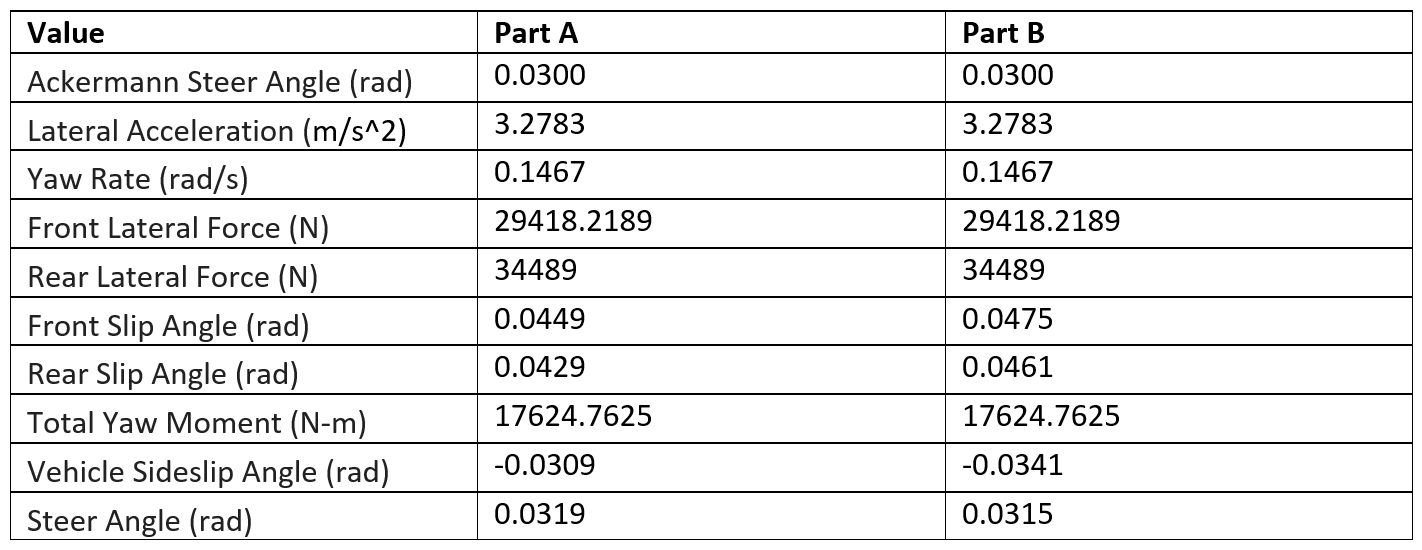

The above table compares various parameters with and without load transfer (i.e., Part A vs Part B). It can be observed that the front as well as rear slip angles increase upon considering the load transfer, since the normal loads acting on inner and outer tires change due to load transfer $\left(\Delta W=\frac{m*a_y *h}{t}\right)$. Consequently, the vehicle slip angle also increases in negative direction. Finally, it is important to note that the steer angle has decreased after considering load transfer. However, in both the cases (with and without load transfer), the actual steer angle is less than the Ackermann steer angle. This implies that the vehicle is understeering in both the cases. However, the fact that the steer angle is reduced from Part A to Part B implies that the vehicle is understeering lesser with load transfer (Part B) than it was without load transfer (Part A).

### Problem 4: Longitudinal Load Transfer and Simulation

#### Part A (Rigid Body Load Transfer):

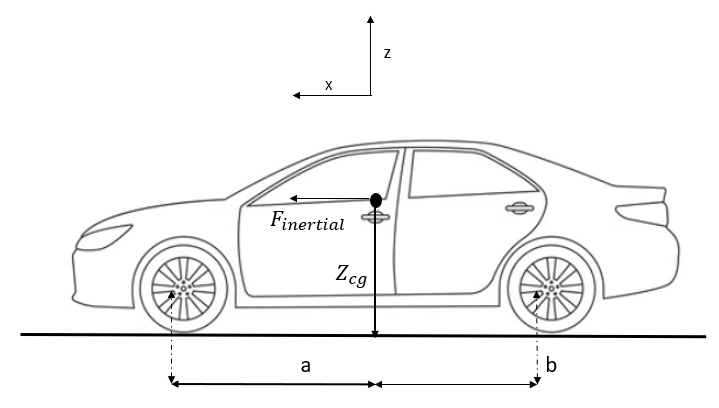

A. Determine the four static wheel loads for a car with the following parameters: mass: 143 slugs, front weight: 54%, left weight: 52%, diagonal weight: 500 N

B. Given the vehicle configuration in the figure, derive an expression for the total rigid body load transfer while braking.

C. With the above parameters and a CG height of 2.3 ft, front, and rear track width of 5.25 ft, wheelbase 9.45 ft, Determine the total amount of load transferred from the rear tires to the front tires when the vehicle is braking at 0.5g!

D. At what longitudinal acceleration will all the load be transferred to the front wheels in a straight-line motion?

#### Part B (Pitch Dynamics):

Derive the equations of motion for a 1 Degree of Freedom (DoF) pitch model. Use the following figure as a reference to develop the equations and apply small angle approximations (linear model).

*(Hint: Take inspiration form the model developed for body roll)*

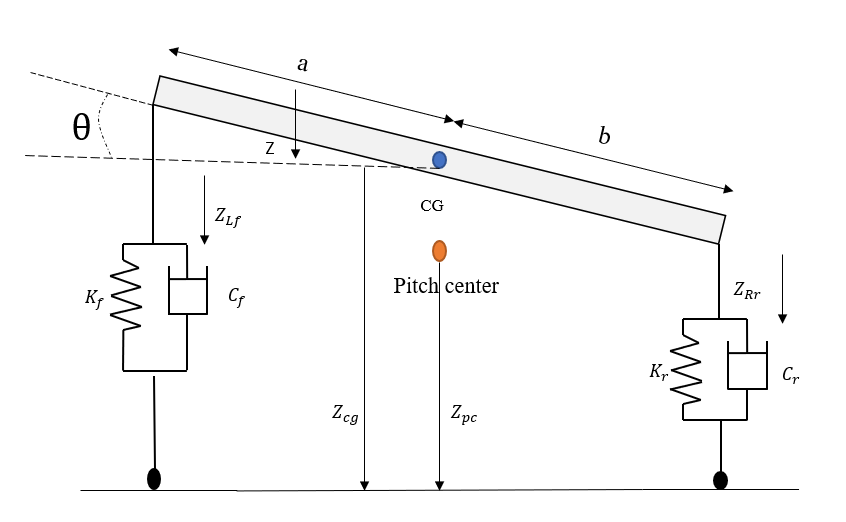

#### Part C (Simulation):

**Parameters:**

- Pitch center height from ground = 1.5 ft.

- Iyy = approximately 40 % of a rectangular block’s (L x W) mass moment of inertia about a transversal axis

- Suspension stiffness

-         Rear: 52 kN/m

-         Front: 45 kN/m

- Initial damping: 0

- Consider the data provided from .mat file which consists of the following information

-         time – seconds

-         acceleration – measured at the CG of vehicle (m/s^2)

-         ride height sensor – placed on top of the suspension strut (m), front and rear

-         velocity – measured in (m/s)

A. Perform a simulation of the derived model and plot the states of the system for step input for an acceleration of – 2 m/s^2.

B. Now, determine the damping coefficient by simulating your above model with the measured acceleration from the data file as an input. Tune the value of damping coefficient manually until you have ‘good’ agreement between measured and simulated data (start with a reasonable value and calculate the coefficient of damper for left and right (assuming they are equal) such that system’s states settle down).

### Solution 4

#### Part A

A. Determine the four static wheel loads for a car with the following parameters: mass: 143 slugs, front weight: 54%, left weight: 52%, diagonal weight: 500 N

% Given data
W = 143; % slugs
W = W*14.594; % kg
W = W*9.81; % N
D = 500; % N
W_X_CG_l = 0.54*W;
W_Y_CG_t = (1-0.52)*W;

Solve system of equations:


$$\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1\\
1 & 1 & 0 & 0\\
0 & 1 & 0 & 1\\
1 & -1 & -1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
F_{z_{\textrm{LF}} } \\
F_{z_{\textrm{RF}} } \\
F_{z_{\textrm{LR}} } \\
F_{z_{\textrm{RR}} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
W\\
\frac{W*X_{\textrm{CG}} }{l}\\
\frac{W*Y_{\textrm{CG}} }{t}\\
D
\end{array}\right\rbrack$$


A = [1  1  1  1;
     1  1  0  0;
     0  1  0  1;
     1 -1 -1  1];
B = [W;
     W_X_CG_l;
     W_Y_CG_t;
     D];
Fz = linsolve(A,B);
fprintf("Static wheel loads are:\n" + ...
        "Left-Front:\t%.4f N\n" + ...
        "Right-Front:\t%.4f N\n" + ...
        "Left-Rear:\t%.4f N\n" + ...
        "Right-Rear:\t%.4f N", Fz(1), Fz(2), Fz(3), Fz(4))

Static wheel loads are:
Left-Front:	5857.4123 N
Right-Front:	5197.9543 N
Left-Rear:	4788.4962 N
Right-Rear:	4629.0382 N

B. Given the vehicle configuration in the figure, derive an expression for the total rigid body load transfer while braking.

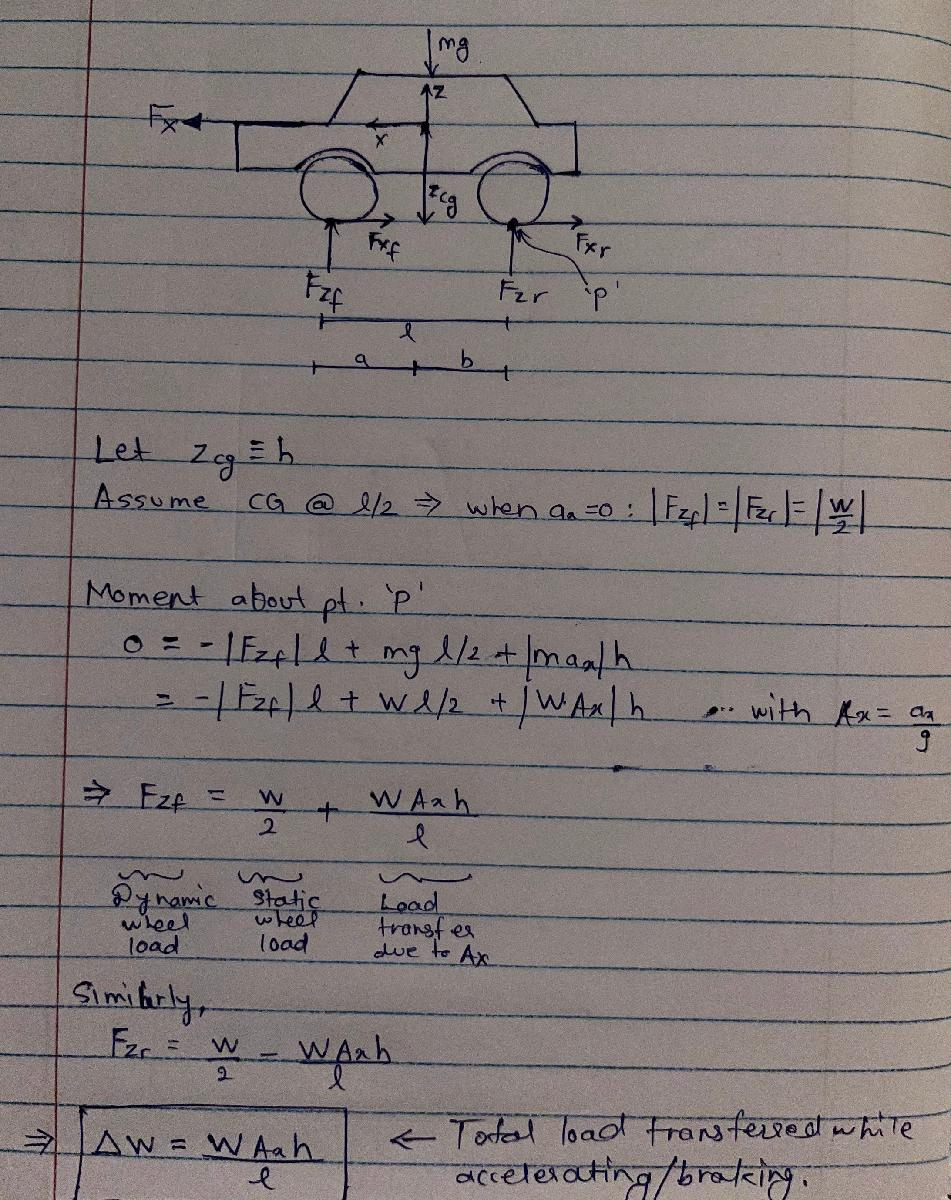

C. With the above parameters and a CG height of 2.3 ft, front, and rear track width of 5.25 ft, wheelbase 9.45 ft, Determine the total amount of load transferred from the rear tires to the front tires when the vehicle is braking at 0.5g!

% Given data
h_cg = 2.3; % ft
h_cg = h_cg/3.281; % m
t = 5.25; % ft
t = t/3.281; % m
l = 9.45; % ft
l = l/3.281; % m
a_x = 0.5; % g
a_x = a_x*9.81; % m/s^2
m = 143; % slugs
m = m*14.594; % kg
dW = (m*a_x*h_cg)/l;
fprintf("The total amount of load transferred from the rear tires to the front tires is " + ...
        "%.4f N",dW)

The total amount of load transferred from the rear tires to the front tires is 2491.4112 N

D. At what longitudinal acceleration will all the load be transferred to the front wheels in a straight-line motion?

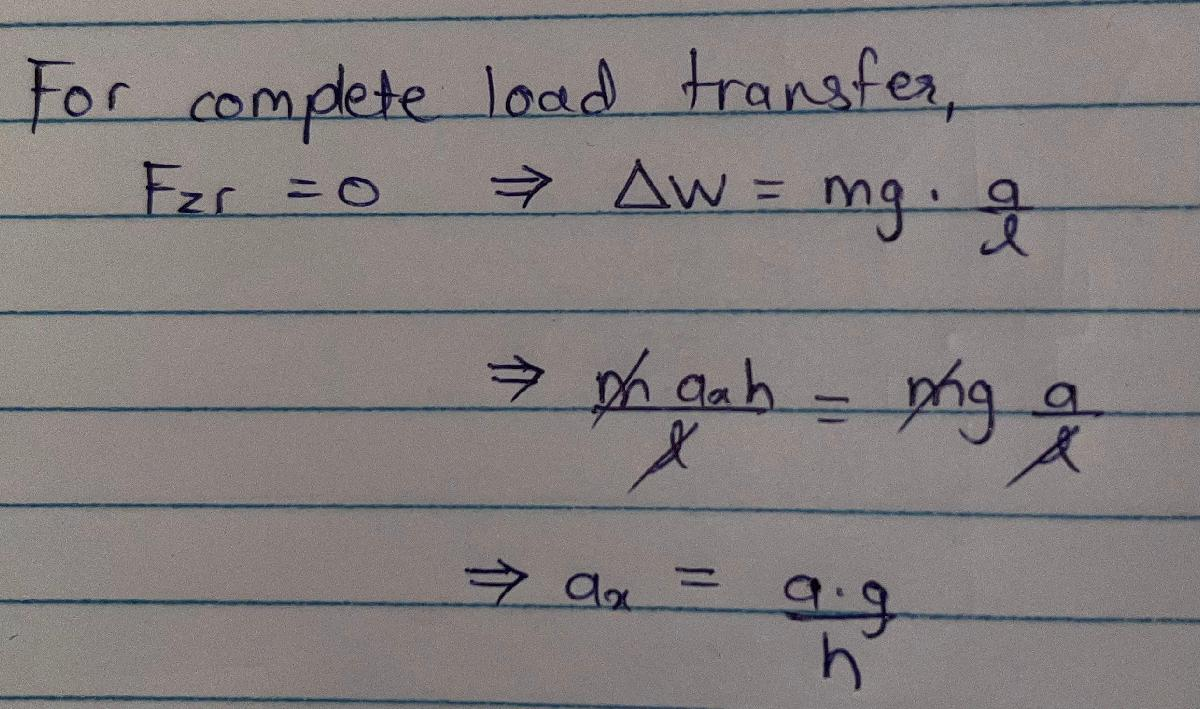

% Given data
a = (1-0.54);
a_x = (a*9.81*l)/(h_cg);
fprintf("All the load be transferred to the front wheels at longitudinal acceleration " + ...
        "of %.4f m/s^2",a_x)

All the load be transferred to the front wheels at longitudinal acceleration of 18.5409 m/s^2

#### Part B

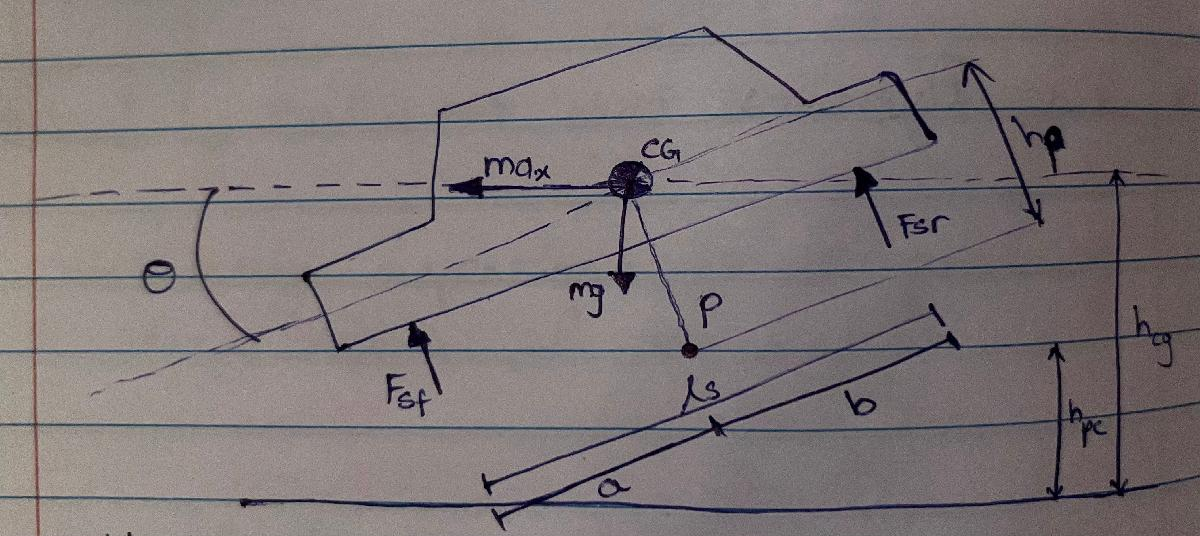

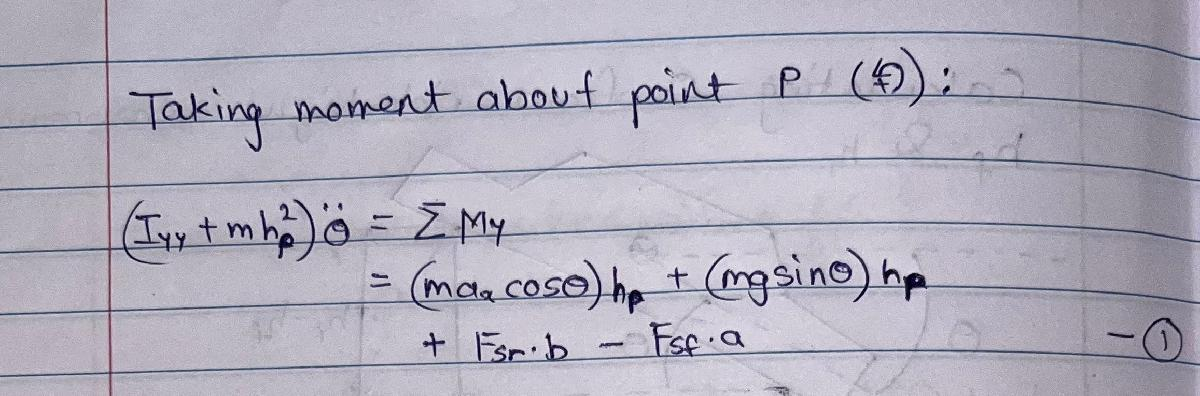

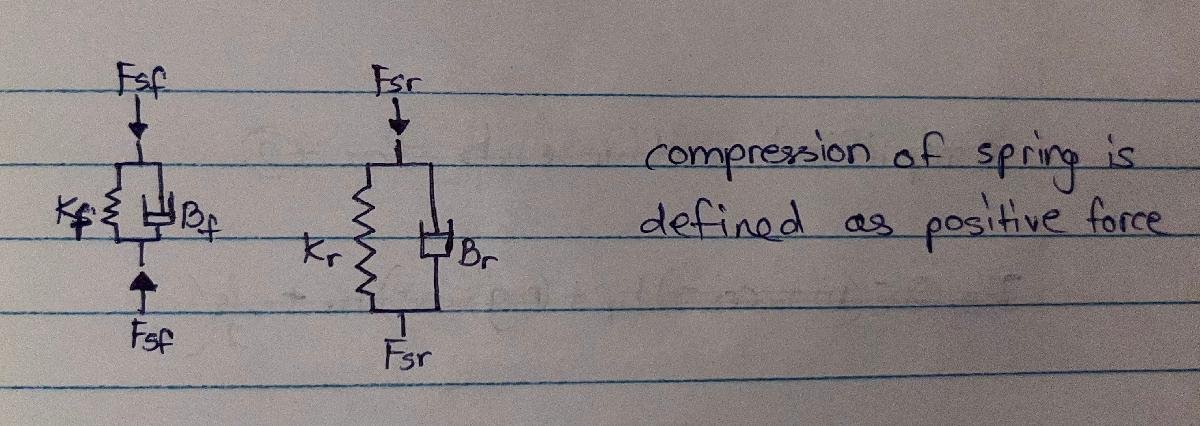

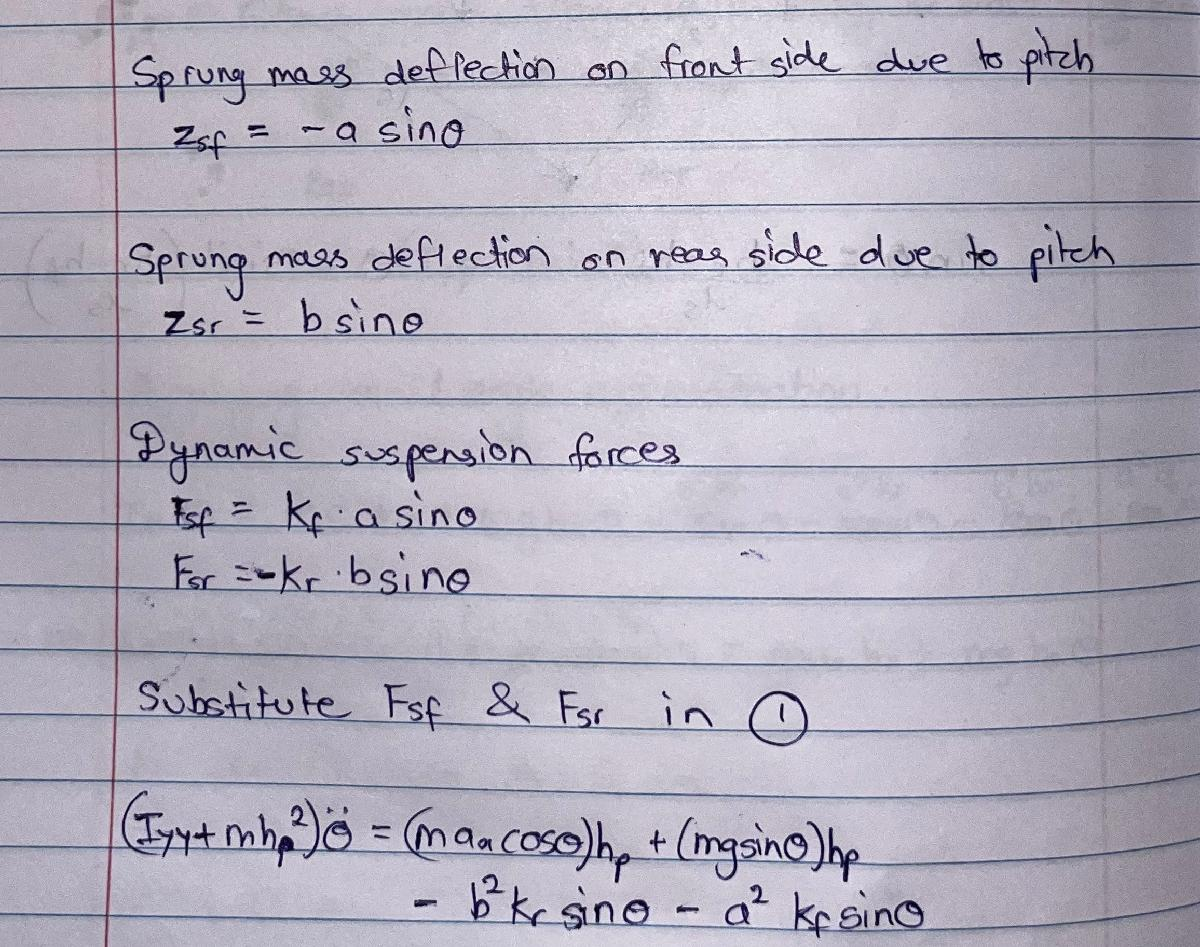

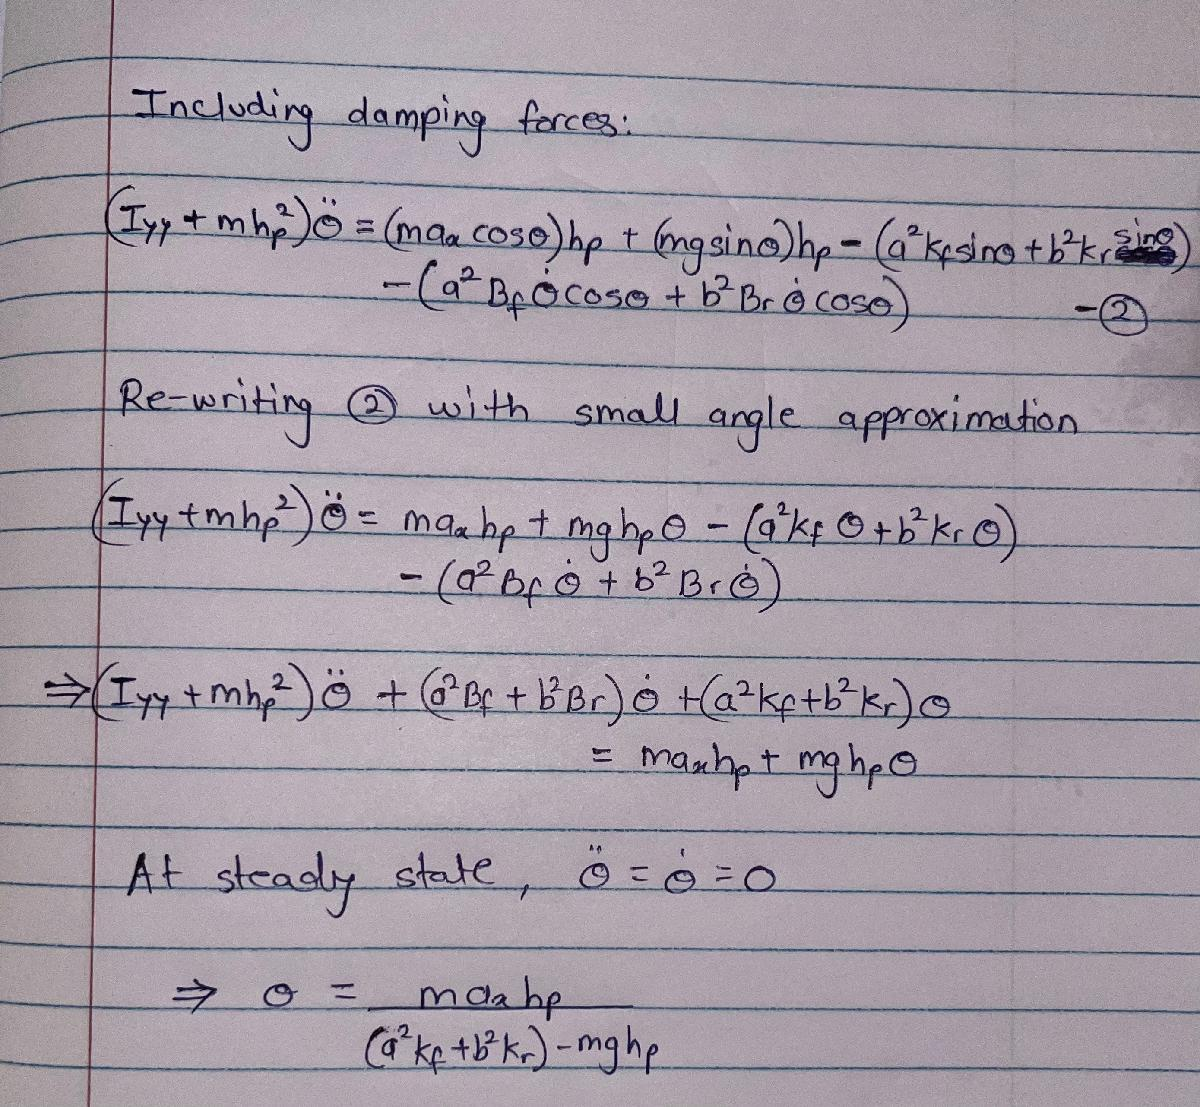

#### Part C

A. Perform a simulation of the derived model and plot the states of the system for step input for an acceleration of – 2 m/s^2.

**Assumptions:**

- $I_{\textrm{yy}}$ = 40% of a rectangular block’s (L=wheelbase x W=trackwidth) mass moment of inertia about a transversal (Y) axis

- Front weight is 54%

- Given suspension stiffness coefficients are $K_r$ and $K_f$ (refer solution to Problem 4 - Part B for notations)

- Given suspension damping coefficients are $B_f$ = $B_r$ = 0 (refer solution to Problem 4 - Part B for notations)

- Initial velocity is taken as first value from `Veh_Speed` variable in `FinalExamData.mat`

- Positive $a_x$ corresponds to braking (refer solution to Problem 4 - Part B for sign convention)

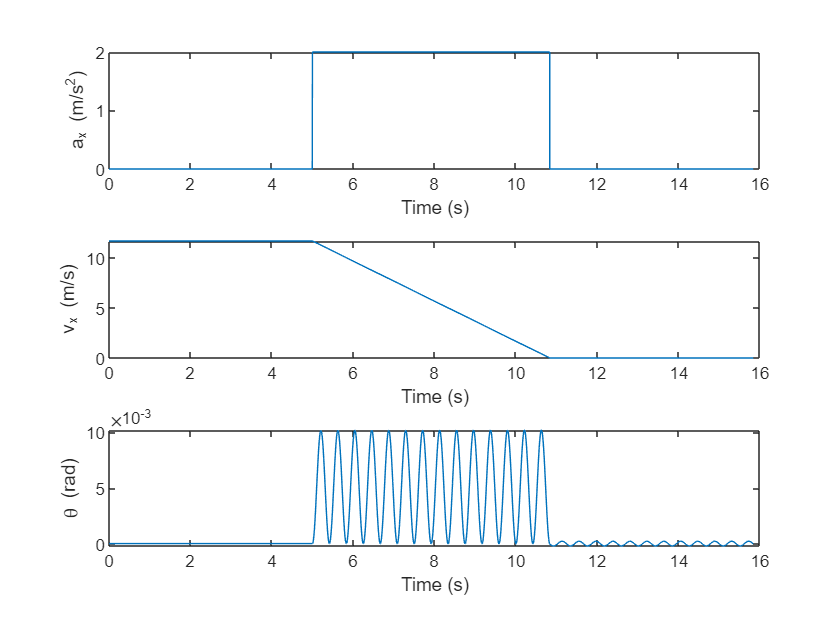

% Given data
h_cg = 2.3; % ft
h_cg = h_cg/3.281; % m
h_pc = 1.5; % ft
h_pc = h_pc/3.281; % m
h_p = h_cg - h_pc; % m
w = 5.25; % ft
w = w/3.281; % m
l = 9.45; % ft
l = l/3.281; % m
a = (1-0.54)*l; % m
b = l-a; % m
a_x = 2; % m/s^2
m = 143; % slugs
m = m*14.594; % kg
K_r = 52e3; % N/m
K_f = 45e3; % N/m
B_r = 0; % Ns/m
B_f = 0; % Ns/m

% Calculate Iyy
Iyy = 0.4*((m/12)*(l^2+w^2)); % kg-m^2

% Initial velocity
load('FinalExamData.mat');
v_x = [];
v_x(1) = Veh_Speed(1); % m/s

% Simulate
theta = [];
theta_dot = [];
theta_ddot = [];
theta(1) = 0;
theta_dot(1) = 0;
dt = 1e-5;
% Constant velocity
for t = 1:5/dt
    a_x(t) = 0;
    theta_ddot(t) = (1/(Iyy+m*h_p^2))*((m*a_x(t)*h_p) + (m*9.81*h_p*theta(t)) - ...
                    ((a^2*B_f + b^2*B_r)*theta_dot(t)) - ((a^2*K_f + b^2*K_r)*theta(t)));
    theta_dot(t+1) = theta_dot(t) + theta_ddot(t)*dt;
    theta(t+1) = theta(t) + theta_dot(t)*dt;
    v_x(t+1) = v_x(t) - a_x(t)*dt;
end
% Braking
while v_x(t) >= 1e-3
    a_x(t) = 2;
    theta_ddot(t) = (1/(Iyy+m*h_p^2))*((m*a_x(t)*h_p) + (m*9.81*h_p*theta(t)) - ...
                    ((a^2*B_f + b^2*B_r)*theta_dot(t)) - ((a^2*K_f + b^2*K_r)*theta(t)));
    theta_dot(t+1) = theta_dot(t) + theta_ddot(t)*dt;
    theta(t+1) = theta(t) + theta_dot(t)*dt;
    v_x(t+1) = v_x(t) - a_x(t)*dt;
    t = t+1;
end
% Zero velocity
for t = t:t+5/dt
    a_x(t) = 0;
    theta_ddot(t) = (1/(Iyy+m*h_p^2))*((m*a_x(t)*h_p) + (m*9.81*h_p*theta(t)) - ...
                    ((a^2*B_f + b^2*B_r)*theta_dot(t)) - ((a^2*K_f + b^2*K_r)*theta(t)));
    theta_dot(t+1) = theta_dot(t) + theta_ddot(t)*dt;
    theta(t+1) = theta(t) + theta_dot(t)*dt;
    v_x(t+1) = 0;
end

% Plot
t = linspace(0,t*dt,t);
figure()
subplot(3,1,1)
plot(t,a_x)
xlabel("Time (s)")
ylabel("a_x (m/s^2)")
subplot(3,1,2)
plot(t,v_x(1:end-1))
xlabel("Time (s)")
ylabel("v_x (m/s)")
subplot(3,1,3)
plot(t,theta(1:end-1))
xlabel("Time (s)")
ylabel("\theta (rad)")

B. Now, determine the damping coefficient by simulating your above model with the measured acceleration from the data file as an input. Tune the value of damping coefficient manually until you have ‘good’ agreement between measured and simulated data (start with a reasonable value and calculate the coefficient of damper for left and right (assuming they are equal) such that system’s states settle down).

**Assumptions:**

- $I_{\textrm{yy}}$ = 40% of a rectangular block’s (L=wheelbase x W=trackwidth) mass moment of inertia about a transversal (Y) axis

- Front weight is 54%

- Given suspension stiffness coefficients are $K_r$ and $K_f$ (refer solution to Problem 4 - Part B for notations)

- Given suspension damping coefficients are $B_f$ = $B_r$ (refer solution to Problem 4 - Part B for notations)

- Initial velocity is taken as first value from `Veh_Speed` variable in `FinalExamData.mat`

- Positive $a_x$ corresponds to braking (refer solution to Problem 4 - Part B for sign convention)

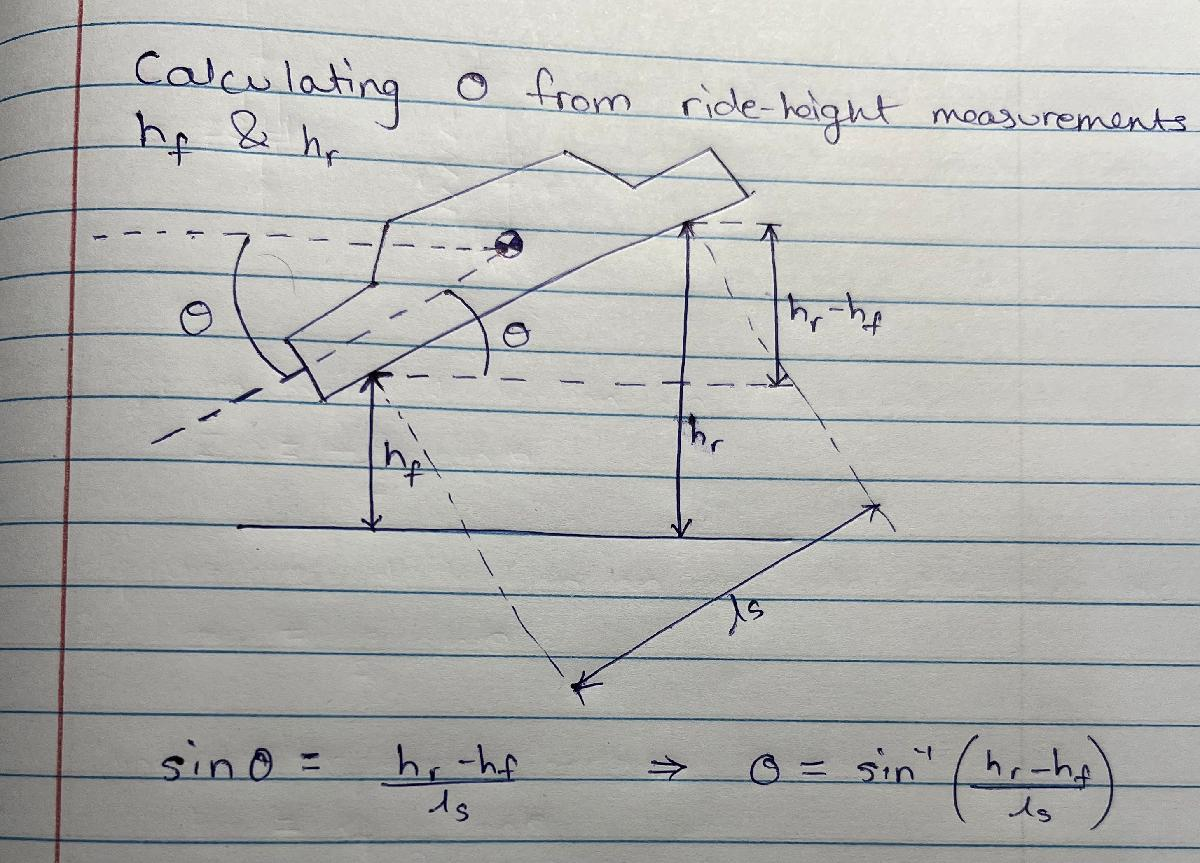

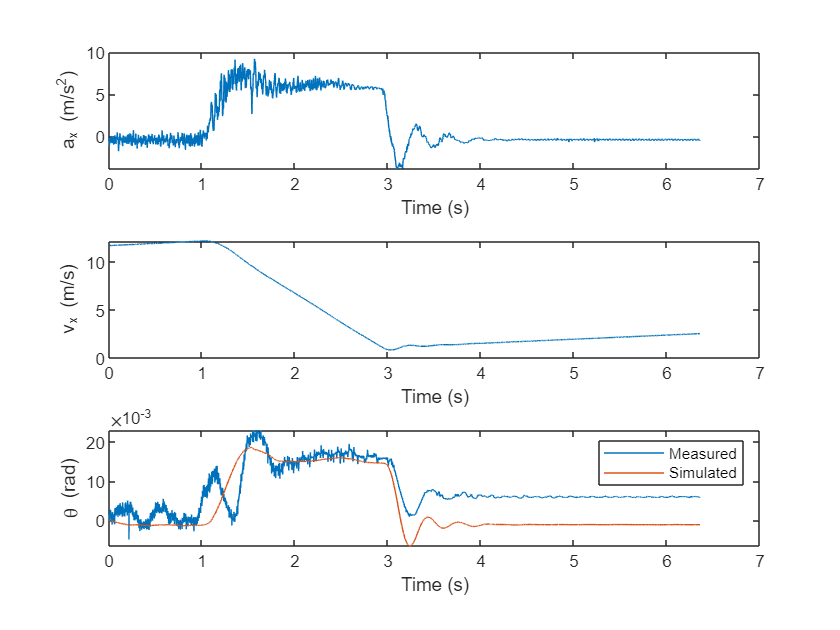

% Given data
h_cg = 2.3; % ft
h_cg = h_cg/3.281; % m
h_pc = 1.5; % ft
h_pc = h_pc/3.281; % m
h_p = h_cg - h_pc; % m
w = 5.25; % ft
w = w/3.281; % m
l = 9.45; % ft
l = l/3.281; % m
a = (1-0.54)*l; % m
b = l-a; % m
a_x = 2; % m/s^2
m = 143; % slugs
m = m*14.594; % kg
K_r = 52e3; % N/m
K_f = 45e3; % N/m
B_r = 4.7e3; % Ns/m
B_f = 4.7e3; % Ns/m

% Calculate Iyy
Iyy = 0.4*((m/12)*(l^2+w^2)); % kg-m^2

% Initial velocity
load('FinalExamData.mat');
v_x = [];
v_x(1) = Veh_Speed(1); % m/s

% Simulate
theta = [];
theta_dot = [];
theta_ddot = [];
theta(1) = 0;
theta_dot(1) = 0;
dt = time(2)-time(1);
for t = 1:length(time)
    a_x(t) = Acc_x(t);
    theta_ddot(t) = (1/(Iyy+m*h_p^2))*((m*a_x(t)*h_p) + (m*9.81*h_p*theta(t)) - ...
                    ((a^2*B_f + b^2*B_r)*theta_dot(t)) - ((a^2*K_f + b^2*K_r)*theta(t)));
    theta_dot(t+1) = theta_dot(t) + theta_ddot(t)*dt;
    theta(t+1) = theta(t) + theta_dot(t)*dt;
    v_x(t+1) = v_x(t) - a_x(t)*dt;
end

% Calculate actual pitch angle using measured data
theta_meas = asin((Rh_lr-Rh_lf)/l);
% Plot
figure()
subplot(3,1,1)
plot(time,a_x)
xlabel("Time (s)")
ylabel("a_x (m/s^2)")
subplot(3,1,2)
plot(time,v_x(1:end-1))
xlabel("Time (s)")
ylabel("v_x (m/s)")
subplot(3,1,3)
plot(time,theta_meas)
hold on
plot(time,theta(1:end-1))
hold off
xlabel("Time (s)")
ylabel("\theta (rad)")
legend("Measured","Simulated")

fprintf("The above plots are generated using B_SR = B_SF = %d Ns/m",B_r)

The above plots are generated using B_SR = B_SF = 4700 Ns/m